% For a transformation matrix T:
%position = T(1:3, 4);          % [x; y; z]
%rotation = T(1:3, 1:3);        % 3x3 rotation matrix

disp('End Effector Position:'); 

End Effector Position:


disp(endEffectorXYZ); % Should match Tb_3(1:3, 4)

    0.1369    0.0000   36.4975



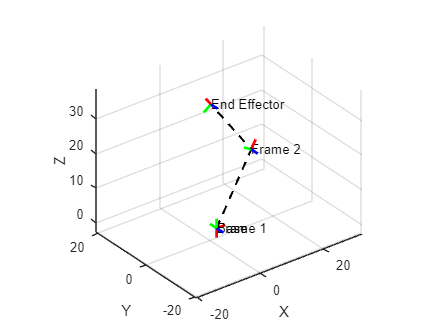


figure;
hold on; grid on; axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
view(3);

% Plot frames and origins
transformation_matrices = {Tb_0, Tb_1, Tb_2, Tb_3};
frame_labels = {'Base', 'Frame 1', 'Frame 2', 'End Effector'};

% Plot each frame
for i = 1:length(transformation_matrices)
    plotFrame(transformation_matrices{i}, frame_labels{i}, 3);
end

% Extract origins as Nx3 matrix (each row: [x, y, z])
origins = cellfun(@(T) T(1:3, 4)', transformation_matrices, 'UniformOutput', false);
origins = vertcat(origins{:}); 

% Connect origins with line 
plot3(origins(:,1), origins(:,2), origins(:,3), 'k--', 'LineWidth', 1.5);

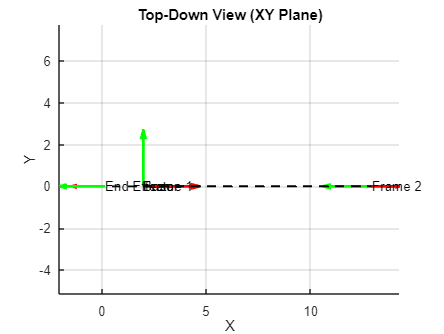


% Debugging
%disp(size(origins)); % Should output 4x3 (for 4 transformation matrices)

% Create a new figure for the top-down view
figure;
hold on; grid on; axis equal;
xlabel('X'); ylabel('Y');
view(2); % Top-down view
title('Top-Down View (XY Plane)');

% Plot frames and links
transformation_matrices = {Tb_0, Tb_1, Tb_2, Tb_3};
frame_labels = {'Base', 'Frame 1', 'Frame 2', 'End Effector'};

% Plot each frame
for i = 1:length(transformation_matrices)
    plotFrame2D(transformation_matrices{i}, frame_labels{i}, 3);
end

% Extract x and y coordinates (ignore z)
origins_2D = cellfun(@(T) T(1:2, 4)', transformation_matrices, 'UniformOutput', false);
origins_2D = vertcat(origins_2D{:});

% Connect origins with lines
plot(origins_2D(:,1), origins_2D(:,2), 'k--', 'LineWidth', 1.5);

% Hide Z-axis
set(gca, 'ZTick', []);

function plotFrame2D(T, label, axis_length)
    % Extract position and orientation
    position = T(1:3, 4);
    rotation = T(1:3, 1:3);
    
    % Project axes onto XY plane (ignore Z)
    X_axis_2D = rotation(1:2,1) * axis_length; % Extract X and Y components
    Y_axis_2D = rotation(1:2,2) * axis_length;
    
    % Plot axes (quiver for 2D)
    quiver(position(1), position(2), X_axis_2D(1), X_axis_2D(2), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    quiver(position(1), position(2), Y_axis_2D(1), Y_axis_2D(2), 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Label the frame
    text(position(1), position(2), label, 'FontSize', 10, 'Color', 'k');
end

function plotFrame(T, label, axis_length)
    % Extract position and orientation
    position = T(1:3, 4);
    rotation = T(1:3, 1:3);
    
    % Define axis directions (scaled for visibility)
    X_axis = rotation(:,1) * axis_length;
    Y_axis = rotation(:,2) * axis_length;
    Z_axis = rotation(:,3) * axis_length;
    
    % Plot axes
    quiver3(position(1), position(2), position(3), X_axis(1), X_axis(2), X_axis(3), 'r', 'LineWidth', 2);
    quiver3(position(1), position(2), position(3), Y_axis(1), Y_axis(2), Y_axis(3), 'g', 'LineWidth', 2);
    quiver3(position(1), position(2), position(3), Z_axis(1), Z_axis(2), Z_axis(3), 'b', 'LineWidth', 2);
    
    % Label the frame
    text(position(1), position(2), position(3), label, 'FontSize', 10, 'Color', 'k');
end